
myfolder = "/Users/emiliathoma/Desktop/docu_tables_und_traces_thoma"

myfolder = "/Users/emiliathoma/Desktop/docu_tables_und_traces_thoma"

filepattern_docu_table = fullfile(myfolder,"*.xlsx")

filepattern_docu_table = "/Users/emiliathoma/Desktop/docu_tables_und_traces_thoma/*.xlsx"

filepattern_supra = fullfile(myfolder,"*supra.txt")

filepattern_supra = "/Users/emiliathoma/Desktop/docu_tables_und_traces_thoma/*supra.txt"

filepattern_connectivity = fullfile(myfolder,"*connectivity.txt")

filepattern_connectivity = "/Users/emiliathoma/Desktop/docu_tables_und_traces_thoma/*connectivity.txt"


filelist_docu_table = dir(filepattern_docu_table);
filelist_supra = dir(filepattern_supra);
filelist_connectivity = dir(filepattern_connectivity);

all_data = struct;

### Einlesen docu_table

for k = 1:length(filelist_docu_table)
    basefilename = filelist_docu_table(k).name;
    fullfilename = fullfile(filelist_docu_table(k).folder, basefilename);
    thisDocuTable = readtable(fullfilename, "VariableNamingRule", "preserve");
    all_data(k).namen= basefilename;
    all_data(k).docutables = thisDocuTable;
end

for k = 1:length(filelist_supra)
    basefilename = filelist_supra(k).name;
    fullfilename = fullfile(filelist_supra(k).folder, basefilename);
    thisSupraTable = table2array(readtable(fullfilename, "VariableNamingRule", "preserve"));
    all_data(k).supra_namen= basefilename;
    all_data(k).supra = thisSupraTable;
    %supratables{k} = thisSupraTable
end

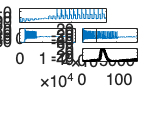

%to check each traces at the time for their firing pattern
trace_segment = all_data(7).supra(:,5);                    
stim_segment=trace_segment(4.8e5:5e5,:);


subplot(5,4,[1:3])

plot(trace_segment)
xlim([0 8.4e5])
subplot(5,4,[5,6])

plot(trace_segment(4.78e5:5.02e5,:))
subplot(5,4,[7,8])

plot(trace_segment(4.8e5:4.88e5,:))
xlim([0 8000])
xline(2000)
xline(2000)

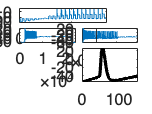


%For test purposes
            diff_threshold = 2;
            AP_time = find(stim_segment>diff_threshold, 1, "first");
            trace_AP = stim_segment(AP_time-50:AP_time+100);

            


subplot(5,4,[11,12,15,16])
            plot(trace_AP, "Color", "k", "LineWidth",2)

            try
            yline(threshold_amplitude)
            xline(threshold_timpoint)
            yline(peak_amplitude)
            yline(half_amplitude)
            xline(first_crossing_of_half_amplitude)
            xline(first_negative_crossing_of_half_amplitude)   
            end




% test= diff(trace_segment)
% AP_time = find(test>diff_threshold, 1, "first")
% AP_time
%             if AP_time < 50
%             trace_AP = trace_segment(1:AP_time+100);
%             else
%             trace_AP = trace_segment(AP_time-50:AP_time+100);
%             end
% 
% figure
% plot(test) 
% figure
% plot(test, 'o')
% 
% yline(2)
%             % try
% xline(AP_time)
%             % end

# tcell

variable_names_types = [["cell_ID", "string"]; ...
			["AP_Amplitude", "double"]; ...
			["half_duration_ms", "double"]; ...
			["type", "string"]; ...
            ["AP_time", "double"]; ...
            ["threshold_timpoint", "double"]; ...
            ["threshold_amplitude", "double"]; ...
            ["peak_amplitude", "double"]; ...
            ["freq_Hz_350pA_0ms_100ms", "double"]; ...
            ["Ap_number_350pA_0ms_100ms", "double"]; ...
            ["freq_Hz_350pA_200ms_400ms", "double"]; ...
            ["Ap_number_350pA_200ms_400ms", "double"]; ...
            ["freq_Hz_300pA_0ms_100ms", "double"]; ...
            ["Ap_number_300pA_0ms_100ms", "double"]; ...
            ["freq_Hz_300pA_200ms_400ms", "double"]; ...
            ["Ap_number_300pA_200ms_400ms", "double"]; ...
            ["freq_Hz_400pA_0ms_100ms", "double"]; ...
            ["Ap_number_400pA_0ms_100ms", "double"]; ...
            ["freq_Hz_400pA_200ms_400ms", "double"]; ...
            ["Ap_number_400pA_200ms_400ms", "double"]; ...
            ["input_resistance", "double"]; ...
            ["downstroke_mVperms", "double"]; ...
            ["hyperpolarisation", "double"]; ...
            ["half_amplitude", "double"]];

% Make table using fieldnames & value types from above
tcell = table('Size',[0,size(variable_names_types,1)],... 
	'VariableNames', variable_names_types(:,1),...
	'VariableTypes', variable_names_types(:,2));


for i=1:size(all_data,2) %durch alle tables durch iterieren
    for channel_n = 1:10 %durch alle 10 channel iterieren
        if all_data(i).docutables{channel_n,2} ==1
            S=strsplit(all_data(i).supra_namen,"_");
            S=strjoin([S(2), S(3)],"_");
            length(tcell.cell_ID)+1
            cellID = append(S,"_C", string(channel_n)); %je nachdem welcher Manipulator ==1, also included war
            tcell.cell_ID(length(tcell.cell_ID)+1,1)=cellID;
        end
    end
end


% stim_current_starts = [0.8e5, 1e5];
% stim_current = [-150e-12, -100e-12, -50e-12];
% Rin_sum=0;
% Rins={};
% for stim_i = 1: 3
% trace_segment = all_data(1).supra(stim_current_starts(1):stim_current_starts(2),5);
%             diff_trace_segment = diff(trace_segment);
%             diff_threshold = 2;
%             AP_time = find(diff_trace_segment>diff_threshold, 1, "first");
%             if isempty(AP_time)==1
%             steadystate=mean(trace_segment);
%             basesegment=(all_data(1).supra(stim_current_starts(1)-20000:stim_current_starts(2)-20000,5));
%             baseline=mean(basesegment);
%             end
% stim_starts = stim_current_starts + [0.4e5, 0.4e5];
% dV=steadystate-baseline
% Rin=(dV)*10^-3/stim_current(stim_i)
% Rins=[Rins, Rin]
% Rin_sum=Rin_sum+Rin
% end
% Rin_sum/stim_i
% Rins


           % stim_starts = [4.8e5, 5e5];
            %if i==2 && channel_n==8
             %   stim_starts = [4.805e5, 5e5];
            %end
            %stim_duration = 1*20e3;
            %trace_segment = data(stim_starts(1):stim_starts(2),1);

            %diff_trace_segment = diff(trace_segment);
            %diff_threshold = 2;
            %AP_time = find(diff_trace_segment>diff_threshold, 1, "first")
           %    AP_time
            % figure
            % plot(trace_segment)
            % plot(diff_trace_segment, 'o')
            % Ap_number=1
            % First_AP_Time=AP_time
            % 
            % AP_time=AP_time+100
            % while AP_time<=2000
            %     freq_segment = data(stim_starts(1)+AP_time:stim_starts(2),1);
            %     stim_starts(1)+AP_time
            %     diff_freq_segment = diff(freq_segment);
            %     AP_time = AP_time+find(diff_freq_segment>diff_threshold, 1, "first")+100
            %     if isempty(AP_time) == 0
            %     Ap_number=Ap_number+1
            %     Last_AP_Time=AP_time-100
            %     end 
            % end
            % period = (Last_AP_Time-First_AP_Time)*0.00005
            % frq_per = Ap_number/period

k=1;
for i=1:size(all_data,2)
    for channel_n = 1:10 %durch alle 10 channel iterieren
        if all_data(i).docutables{channel_n,2} ==1
            data=all_data(i).supra(:,channel_n+1);
            stim_starts = [4.8e5, 5e5];
            stim_starts_before = [4.4e5, 4.6e5]; %to later test for freq in different stimulation timepoints
            stim_starts_after = [5.2e5, 5.4e5]; %to later test for freq in different stimulation timepoints
            %if i==2 && channel_n==8
            %    stim_starts = [4.805e5, 5e5];
            %end
            
            stim_duration = 1*20e3;
            trace_segment = data(stim_starts(1):stim_starts(2),1);
            % figure
            % plot(trace_segment)

            diff_trace_segment = diff(trace_segment);
            %downstroke in mV/ms
            max_downstroke_tik = min(diff_trace_segment);
            max_downstroke = max_downstroke_tik*20;
            try
            tcell.downstroke_mVperms(k)=max_downstroke;
    
            diff_threshold = 2;
            AP_time = find(diff_trace_segment>diff_threshold, 1, "first");
            
            
           
            % figure
            % % plot(diff_trace_segment, 'o')
            % % yline(2)
            % try
            % xline(AP_time)
            % end

            %extract the AP
            if AP_time < 50
            trace_AP = trace_segment(1:AP_time+100);
            else
            trace_AP = trace_segment(AP_time-50:AP_time+100);
            end
            tcell.AP_time(k)=AP_time;

            %threshold amplitude
            try
            threshold_timpoint = find(diff(trace_AP)>diff_threshold, 1, 'first');
            tcell.threshold_timpoint(k)=threshold_timpoint;
            threshold_amplitude = trace_AP(threshold_timpoint);
            tcell.threshold_amplitude(k)=threshold_amplitude;
            end

            %get the peak amplitude
            peak_amplitude = max(trace_AP);
            tcell.peak_amplitude(k) = peak_amplitude;

            %AP amplitude
            ap_amplitude = peak_amplitude-threshold_amplitude;
            tcell.AP_Amplitude(k)=ap_amplitude;

            %Hyperpolarisation
            try
            trace_AP_hyper_timeframe = trace_segment(AP_time-10:AP_time+100);
            hyperpolarisation = min(trace_AP_hyper_timeframe);
            tcell.hyperpolarisation(k)=hyperpolarisation;
            end

            %ap half duration:
            try
            half_amplitude = threshold_amplitude + (ap_amplitude/2);
            tcell.half_amplitude(k)=half_amplitude;
            first_crossing_of_half_amplitude = find(trace_AP>half_amplitude,1,"first");
            first_negative_crossing_of_half_amplitude = ...
                find(trace_AP(first_crossing_of_half_amplitude:end)<half_amplitude,1, "first") + first_crossing_of_half_amplitude;

            %half duration
            half_duration = first_negative_crossing_of_half_amplitude-first_crossing_of_half_amplitude;
            tcell.half_duration_ms(k)=half_duration/20;
            end
            end

            %input resistance
            stim_current_starts = [0.8e5, 1e5];
            stim_current = [-150e-12, -100e-12, -50e-12];
            Rin_sum=0;
            Rins={};
            Rin_avg=0;
            for stim_i = 1: 3
                trace_segment_res = all_data(i).supra(stim_current_starts(1):stim_current_starts(2),channel_n+1);
                diff_trace_segment_res = diff(trace_segment_res);
                diff_threshold = 2;
                AP_time_res = find(diff_trace_segment_res>diff_threshold, 1, "first");
                if isempty(AP_time_res)==1
                    steadystate=mean(trace_segment_res);
                    basesegment=(all_data(1).supra(stim_current_starts(1)-20000:stim_current_starts(2)-20000,channel_n+1));
                    baseline=mean(basesegment);
                end
                stim_current_starts = stim_current_starts + [0.4e5, 0.4e5];
                dV=steadystate-baseline;
                Rin=(dV)*10^-3/stim_current(stim_i);
                Rins=[Rins, Rin];
                Rin_sum=Rin_sum+Rin;
            end
            Rin_avg=Rin_sum/stim_i;
            %Tabele mit input resistances pro manip.
            Rins;
            tcell.input_resistance(k)=Rin_avg;
            


            %freq
            % figure
            % plot(trace_segment)
            

            
            %350pA

            try
            Ap_number=1;
            First_AP_Time=AP_time;

            AP_time_freq=AP_time+100;
            while AP_time_freq<=2000
                freq_segment = data(stim_starts(1)+AP_time_freq:stim_starts(2),1);
                stim_starts(1)+AP_time_freq;
                diff_freq_segment = diff(freq_segment);
                AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                if isempty(AP_time_freq) == 0 && AP_time_freq < 2000
                Ap_number=Ap_number+1;
                Last_AP_Time=AP_time_freq-100;
                end 
            end
            end

            %tik in sekunde

           
            try
            period = (Last_AP_Time-First_AP_Time)*0.00005;
            frq_per_0_100 = Ap_number/period;
            tcell.freq_Hz_350pA_0ms_100ms(k)=frq_per_0_100;
            tcell.Ap_number_350pA_0ms_100ms(k)= Ap_number;

            Ap_number=0; 
            AP_time_freq=4000;
            First_AP_Time=4000;
            while AP_time_freq<=8000
                 freq_segment = data(stim_starts(1)+AP_time_freq:stim_starts(2),1);
                 stim_starts(1)+AP_time_freq;
                 diff_freq_segment = diff(freq_segment);
                 AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                 if isempty(AP_time_freq) == 0 && AP_time_freq < 8000
                 Ap_number=Ap_number+1;
                 Last_AP_Time=AP_time_freq-100;
                 end 
             end
             period = (Last_AP_Time-First_AP_Time)*0.00005;
             frq_per_200_400 = Ap_number/period;
            tcell.freq_Hz_350pA_200ms_400ms(k)=frq_per_200_400;
            tcell.Ap_number_350pA_200ms_400ms(k)=Ap_number;
            end


            % 300 pA
             
            trace_segment_before = data(stim_starts_before(1):stim_starts_before(2),1);
            diff_trace_segment_before = diff(trace_segment_before);
            diff_threshold = 2;
            AP_time_before = find(diff_trace_segment_before>diff_threshold, 1, "first");

try
            Ap_number=1;
            First_AP_Time=AP_time_before;

            AP_time_freq=AP_time_before+100;
            while AP_time_freq<=2000
                freq_segment_before = data(stim_starts_before(1)+AP_time_freq:stim_starts_before(2),1);
                stim_starts_before(1)+AP_time_freq;
                diff_freq_segment_before = diff(freq_segment_before);
                AP_time_freq = AP_time_freq+find(diff_freq_segment_before>diff_threshold, 1, "first")+100;
                if isempty(AP_time_freq) == 0 && AP_time_freq < 2000
                Ap_number=Ap_number+1;
                Last_AP_Time=AP_time_freq-100;
                end 
            end
            end

            %tik in sekunde

            
            try
            period = (Last_AP_Time-First_AP_Time)*0.00005;
            frq_per_0_100 = Ap_number/period;
            tcell.freq_Hz_300pA_0ms_100ms(k)=frq_per_0_100;
            tcell.Ap_number_300pA_0ms_100ms(k)= Ap_number;

            Ap_number=0; 
            AP_time_freq=4000;
            First_AP_Time=4000;
            while AP_time_freq<=8000
                 freq_segment_before = data(stim_starts_before(1)+AP_time_freq:stim_starts_before(2),1);
                 stim_starts_before(1)+AP_time_freq;
                 diff_freq_segment = diff(freq_segment_before);
                 AP_time_freq = AP_time_freq+find(diff_freq_segment_before>diff_threshold, 1, "first")+100;
                 if isempty(AP_time_freq) == 0 && AP_time_freq < 8000
                 Ap_number=Ap_number+1;
                 Last_AP_Time=AP_time_freq-100;
                 end 
             end
             period = (Last_AP_Time-First_AP_Time)*0.00005;
             frq_per_200_400 = Ap_number/period;
            tcell.freq_Hz_300pA_200ms_400ms(k)=frq_per_200_400;
            tcell.Ap_number_300pA_200ms_400ms(k)=Ap_number;
            end



            % 400 pA
            trace_segment_after = data(stim_starts_after(1):stim_starts_after(2),1);
            diff_trace_segment_after = diff(trace_segment_after);
            diff_threshold = 2;
            AP_time_after = find(diff_trace_segment_after>diff_threshold, 1, "first");


try
            Ap_number=1;
            First_AP_Time=AP_time_after;

            AP_time_freq=AP_time_after+100;
            while AP_time_freq<=2000
                freq_segment_after = data(stim_starts_after(1)+AP_time_freq:stim_starts_after(2),1);
                stim_starts_after(1)+AP_time_freq;
                diff_freq_segment_after = diff(freq_segment_after);
                AP_time_freq = AP_time_freq+find(diff_freq_segment_after>diff_threshold, 1, "first")+100;
                if isempty(AP_time_freq) == 0 && AP_time_freq < 2000
                Ap_number=Ap_number+1;
                Last_AP_Time=AP_time_freq-100;
                end 
            end
            end

            %tik in sekunde

            
            try
            period = (Last_AP_Time-First_AP_Time)*0.00005;
            frq_per_0_100 = Ap_number/period;
            tcell.freq_Hz_400pA_0ms_100ms(k)=frq_per_0_100;
            tcell.Ap_number_400pA_0ms_100ms(k)= Ap_number;

            Ap_number=0; 
            AP_time_freq=4000;
            First_AP_Time=4000;
            while AP_time_freq<=8000
                 freq_segment_after = data(stim_starts_after(1)+AP_time_freq:stim_starts_after(2),1);
                 stim_starts_after(1)+AP_time_freq;
                 diff_freq_segment_after = diff(freq_segment_after);
                 AP_time_freq = AP_time_freq+find(diff_freq_segment_after>diff_threshold, 1, "first")+100;
                 if isempty(AP_time_freq) == 0 && AP_time_freq < 8000
                 Ap_number=Ap_number+1;
                 Last_AP_Time=AP_time_freq-100;
                 end 
             end
             period = (Last_AP_Time-First_AP_Time)*0.00005;
             frq_per_200_400 = Ap_number/period;
            tcell.freq_Hz_400pA_200ms_400ms(k)=frq_per_200_400;
            tcell.Ap_number_400pA_200ms_400ms(k)=Ap_number;
            end



            % figure
            % plot(trace_AP, "Color", "k", "LineWidth",2)
            %try
            %yline(threshold_amplitude)
            %xline(threshold_timpoint)
            %yline(peak_amplitude)
            %yline(half_amplitude)
            %xline(first_crossing_of_half_amplitude)
            %xline(first_negative_crossing_of_half_amplitude)   
            k=k+1
            
        end
    end
end 

writetable(tcell,"/Users/emiliathoma/Desktop/results_supra_rat_stim_350pA.csv" )

% data=all_data(27).supra(:,2)
% plot(data)
%             stim_starts = [4.8e5, 5e5]
% 
%             stim_duration = 1*20e3;
%             trace_segment = data(stim_starts(1):stim_starts(2),1)
%             figure
%             plot(trace_segment)
% 
%             diff_trace_segment = diff(trace_segment)
%             %downstroke in mV/ms
%             max_downstroke_tik = min(diff_trace_segment)
%             max_downstroke = max_downstroke_tik*20
%             diff_threshold = 2
%             AP_time = find(diff_trace_segment>diff_threshold, 1, "first")
% 


% for k = 1:length(all_data.supra)
%     workingsupra = supratables{k}
%     for i = 2:11
% 
%         %Stimulation time points:
%         stim_starts = [4.2e5, 4.4e5];
%         stim_duration = 1*20e3;
% 
%         for stim_number=1:size(stim_starts,2)
%             trace_segment = workingsupra(stim_starts(stim_number):stim_starts(stim_number)+stim_duration,[1,i]);
%             figure
%             name = string(fieldnames(trace_segment))
% 
%             plot(trace_segment,"s",name(2))
%             diff_trace_segment = diff(trace_segment.(name(2)));
% 
%             %detect action potential when derivative exceeds
%             diff_threshold = 2;
%             AP_index = find(diff_trace_segment>diff_threshold, 1, "first")
%             AP_time = table2array(trace_segment(AP_index,1))
% 
%             figure
%             plot(diff_trace_segment, 'o')
%             yline(2)
%             try
%             xline(AP_time)
%             end
% 
%             %extract the AP
%             try
%             trace_AP = trace_segment(AP_index-50:AP_index+100,name(2))
%             diff_AP_segment = diff(trace_AP.(name(2)));
% 
%             %Get the first values to publish in my paper:
%             %threshold amplitude
%             threshold_timpoint = find(diff_AP_segment>diff_threshold, 1, 'first')
%             threshold_amplitude = table2array(trace_AP(threshold_timpoint, name(2)))
%             %get the peak amplitude
%             peak_amplitude = table2array(max(trace_AP(:, name(2))))
%             %AP amplitude
%             ap_amplitude = peak_amplitude-threshold_amplitude
%             %ap half duration
%             half_amplitude = threshold_amplitude + (ap_amplitude/2)
%             first_crossing_of_half_amplitude = find(table2array(trace_AP)>half_amplitude,1,"first")
%             AP_array = table2array(trace_AP)
%             first_negative_crossing_of_half_amplitude = find((AP_array(first_crossing_of_half_amplitude:end))<half_amplitude,1, "first") + first_crossing_of_half_amplitude
%             half_duration = first_negative_crossing_of_half_amplitude-first_crossing_of_half_amplitude
% 
%             trace_AP.s=table2array(trace_segment((AP_index-50:AP_index+100),"s"))
%             figure
%             plot(trace_AP, "s",name(2))
%             try
%             yline(threshold_amplitude)
%             xline(traceAP(threshold_timpoint:"s"))
%             yline(peak_amplitude)
%             yline(half_amplitude)
%             xline(traceAP(first_crossing_of_half_amplitude:"s"))
%             xline(traceAP(first_negative_crossing_of_half_amplitude:"s"))
%             end
%             k=k+1
%             end
% % end
% 
% 
% 
%     end
% end

clearvars
